%==========================================================================
% Author:    Naghmeh Akhavan, PhD
% Affil.:    University of Michigan, Ann Arbor
% Contact:   nakhavan@umich.edu
%
%
% Last updated: March 2026
%==========================================================================

clear; clc; close all;

%% ---------------- RNG ----------------
RNG_SEED = 1;
rng(RNG_SEED);

%% ---------------- USER PATHS ----------------
combinedFolder   = 'C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\combined_out';
matR_fallback    = fullfile(combinedFolder, 'Combined_BigResultTable.mat');

%% ---------------- SETTINGS ----------------
WAKE_BREAK_MIN   = 2;
WAKE_BREAK_SEC   = 60*WAKE_BREAK_MIN;

nbinsHist        = 60;
PLOT_MIXTURE     = true;

XMIN             = 0.5;  % minutes
GRID_STEP        = 0.5;  % minutes (30s epochs)

% Discrete GOF / bootstrap
DO_DISCRETE_GOF  = true;
GOF_MODE         = "refit";   % "refit" or "plugin"
B_BOOT           = 1000;       % use 500-1000 for paper
ALPHA_P          = 0.05;
MIN_EXP          = 5;         
PRINT_NULL_SUMMARY = true;

% STEP 1: we try these mapping rules (lumped)
MAP_TEST = ["floor","ceil","nearest"];

% Choose mapping for per-bin section:
%   - set to "auto" to pick the mapping with largest p(KS) (tie-break: p(CvM))
%   - or set explicitly to "floor" / "ceil" / "nearest"
MAP_CHOSEN = "auto";

% STEP 2: print first few grid probabilities
PROB_POINTS = [0.5 1.0 1.5 2.0 2.5];  % minutes

%% ---------------- EM options ----------------
opts = struct();
opts.nStarts   = 25;
opts.maxIter   = 250;
opts.tol       = 1e-7;
opts.trimFrac  = 0.01;
opts.wMin      = 0.02;
opts.wMax      = 0.98;

opts.rMin      = 1e-4;
opts.rMax      = 5.0;

opts.sigMinTN  = 0.25;
opts.sigMaxTN  = 200.0;

opts.MU_FLOOR_Q            = 0.10;
opts.MU_FLOOR_MIN          = 0.0;
opts.ENFORCE_TN_LONG_COND  = true;
opts.Q_TN_LONG             = 0.70;
opts.LONGTAIL_QCHECK       = 0.90;
opts.LONGTAIL_MIN_MINUTES  = 25;

optsBoot = opts;
optsBoot.nStarts = 10;   % speed for refit bootstrap; we can set 25 for max accuracy

%% ---------------- LOAD DATA (UNFILTERED) ----------------
assert(isfile(matR_fallback), 'Missing Combined_BigResultTable.mat:\n  %s', matR_fallback);
Sfb = load(matR_fallback);
assert(isfield(Sfb,'Combined_BigResultTable'), 'MAT file lacks Combined_BigResultTable.');
T = Sfb.Combined_BigResultTable;

fprintf('Loaded UNFILTERED Combined_BigResultTable:\n  %s\n', matR_fallback);

Loaded UNFILTERED Combined_BigResultTable:
  C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\combined_out\Combined_BigResultTable.mat



%% ========================================================================
%  SUBJECT-LEVEL OUTLIER FILTER BY # REM CYCLES (IQR rule)
%==========================================================================

DO_CYCLECOUNT_IQR_FILTER = true;
IQR_MULT = 1.5;

if DO_CYCLECOUNT_IQR_FILTER
    assert(ismember('REM_Cycle_Index', T.Properties.VariableNames), ...
        'REM_Cycle_Index column not found in table.');

    cycleID = string(T.REM_Cycle_Index);
    subjAll = extractBefore(cycleID, "_C");
    cnumAll = str2double(extractAfter(cycleID, "_C"));

    okCC = isfinite(cnumAll) & cnumAll>0 & strlength(subjAll)>0;
    subjAll = subjAll(okCC);
    cnumAll = cnumAll(okCC);

    [G, subjList] = findgroups(subjAll);
    cyclesPerSubj = splitapply(@max, cnumAll, G);

    Q1 = prctile(cyclesPerSubj, 25);
    Q3 = prctile(cyclesPerSubj, 75);
    IQRv = Q3 - Q1;

    lowerBound = Q1 - IQR_MULT*IQRv;
    upperBound = Q3 + IQR_MULT*IQRv;

    isOut = (cyclesPerSubj < lowerBound) | (cyclesPerSubj > upperBound);
    outSubj = subjList(isOut);

    fprintf('\nCycle-count IQR filter:\n');
    fprintf('  Q1=%.2f, Q3=%.2f, IQR=%.2f\n', Q1, Q3, IQRv);
    fprintf('  Bounds: [%.2f, %.2f]\n', lowerBound, upperBound);
    fprintf('  Subjects total=%d | outliers=%d\n', numel(subjList), numel(outSubj));

    if ~isempty(outSubj)
        fprintf('  Outlier subjects (by cycle count):\n');
        disp(outSubj);

        subjT = extractBefore(string(T.REM_Cycle_Index), "_C");
        dropRows = ismember(subjT, outSubj);

        nBefore = height(T);
        T = T(~dropRows, :);
        fprintf('  Dropped rows: %d | kept rows: %d (from %d)\n', ...
            sum(dropRows), height(T), nBefore);
    else
        fprintf('  No cycle-count outliers detected.\n');
    end
end


Cycle-count IQR filter:


  Q1=5.00, Q3=11.00, IQR=6.00


  Bounds: [-4.00, 20.00]


  Subjects total=573 | outliers=21


  Outlier subjects (by cycle count):


    "MNC371"
    "MNC389"
    "MNC418"
    "MNC462"
    "MNC496"
    "MNC523"
    "MNC530"
    "MNC534"
    "MNC540"
    "MNC549"
    "MNC551"
    "MNC561"
    "MNC583"
    "SC4041EC"
    "SC4042EC"
    "SC4072EH"
    "SC4291GA"
    "SC4312EM"
    "SC4611EG"
    "SC4652EG"
    "SC4762EG"



  Dropped rows: 596 | kept rows: 4426 (from 5022)



%% ---------------- ENSURE REQUIRED NUMERIC COLUMNS ----------------
needNum = ["REMpre","NREM","IREM","Wake","Movement"];
for v = needNum
    if ~ismember(v, string(T.Properties.VariableNames))
        T.(v) = NaN(height(T),1);
    end
    T.(v) = double(T.(v));
end

if all(isnan(T.IREM)) && all(ismember(["NREM","Wake","Movement"], string(T.Properties.VariableNames)))
    T.IREM = T.NREM + T.Wake + T.Movement;
end

%% ---------------- IN-SCRIPT LONG-WAKE FILTER (>= WAKE_BREAK_MIN) ---------
n0 = height(T);

wakeSec = T.Wake;
if all(isnan(wakeSec))
    movSec = T.Movement;
    if all(isnan(movSec)), movSec = zeros(height(T),1); end
    if all(isfinite(T.IREM)) && all(isfinite(T.NREM))
        wakeSec = T.IREM - T.NREM - movSec;
    else
        wakeSec = NaN(height(T),1);
    end
end
wakeSec(~isfinite(wakeSec)) = NaN;

keepLW = true(height(T),1);
knownWake = isfinite(wakeSec);
keepLW(knownWake) = wakeSec(knownWake) < WAKE_BREAK_SEC;

T = T(keepLW,:);

fprintf('\nIn-script long-wake DROP applied: Wake >= %d min (%d sec)\n', ...
    WAKE_BREAK_MIN, WAKE_BREAK_SEC);


In-script long-wake DROP applied: Wake >= 2 min (120 sec)


fprintf('  Rows before: %d | kept: %d | dropped: %d\n', n0, height(T), n0-height(T));

  Rows before: 4426 | kept: 2951 | dropped: 1475



%% ---------------- BUILD POOLED DATA (minutes) ----------------
RP_min = T.REMpre/60;
N_min  = T.NREM/60;

ok = isfinite(RP_min) & RP_min>0 & isfinite(N_min) & (N_min >= XMIN);
RP_min = RP_min(ok);
x_all  = N_min(ok);

% Confirm exact 0.5-min grid
assert(all(abs(x_all/GRID_STEP - round(x_all/GRID_STEP))<1e-12), ...
    'x_all not on GRID_STEP grid; adjust GRID_STEP or data processing.');

fprintf('Valid pooled NREM cycles after LW drop and x>=%.2f: n = %d\n', XMIN, numel(x_all));

Valid pooled NREM cycles after LW drop and x>=0.50: n = 2433



%% ========================================================================
%  LUMPED FIT
%==========================================================================

fitL = fit_atom_e1tn(x_all, opts, XMIN);

fprintf('\n==== LUMPED atom+ (E1-short + TN@xmin) ====\n');


==== LUMPED atom+ (E1-short + TN@xmin) ====


print_fit_console_atom(fitL);

a (atom at xmin) = 0.2922
w_cont = [0.7481 0.2519]
E1-short: r=0.108132
TN@xmin: mu=65.5819, sig=16.6177
LL=-5504.397243 | BIC=11046.05 | n=2433 | n_cont=1722


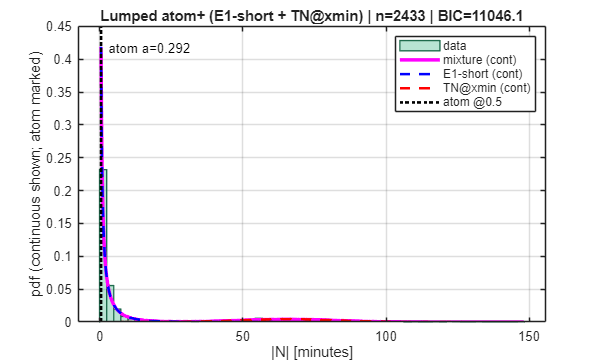


% Plot lumped (pdf overlay)
figure('Color','w','Position',[140 120 900 540]);
face = [0.2 0.7 0.5];
edge = face*0.6;

histogram(x_all, nbinsHist, 'Normalization','pdf', ...
    'FaceColor',face,'FaceAlpha',0.35,'EdgeColor',edge,'LineWidth',1.0);
hold on;

xx = linspace(min(x_all), max(x_all), 900);
[yy, comps] = atom_e1tn_pdf_components(xx, fitL, XMIN);

if PLOT_MIXTURE
    plot(xx, yy, 'm-', 'LineWidth',2.6);
end
plot(xx, comps(:,1), 'b--', 'LineWidth',1.9);
plot(xx, comps(:,2), 'r--', 'LineWidth',1.9);

yl = ylim;
plot([XMIN XMIN], yl, 'k:', 'LineWidth',2.0);
text(XMIN, 0.95*yl(2), sprintf('  atom a=%.3f', fitL.a), 'Color','k', 'VerticalAlignment','top');

grid on; box on;
xlabel('|N| [minutes]');
ylabel('pdf (continuous shown; atom marked)');
title(sprintf('Lumped atom+ (E1-short + TN@xmin) | n=%d | BIC=%.1f', numel(x_all), fitL.BIC), 'Interpreter','none');
legend({'data','mixture (cont)','E1-short (cont)','TN@xmin (cont)','atom @0.5'}, 'Location','northeast');


%% ========================================================================
%  STEP 1: Test discretization mappings on LUMPED data
%  STEP 2: Print observed vs model probabilities at early grid points
%==========================================================================

best = struct('map',"floor",'pKS',-Inf,'pCvM',-Inf);

if DO_DISCRETE_GOF
    fprintf('\n==================== STEP 1: mapping comparison (LUMPED) ====================\n');

    for mm = 1:numel(MAP_TEST)
        mapMode = MAP_TEST(mm);

        fprintf('\n---- DISCRETE GOF (Δ=%.2f min, xmin=%.2f) | mapping=%s | mode=%s ----\n', ...
            GRID_STEP, XMIN, mapMode, GOF_MODE);

        statsObs = discrete_gof_stats(x_all, fitL, XMIN, GRID_STEP, MIN_EXP, mapMode);

        fprintf('Observed discrete GOF:\n');
        fprintf('  KS_grid  = %.6f\n', statsObs.KS);
        fprintf('  CvM_grid = %.6f\n', statsObs.CvM);
        fprintf('  Chi2     = %.6f (bins=%d)\n', statsObs.Chi2, statsObs.nBinsUsed);
        fprintf('  Gtest    = %.6f (bins=%d)\n', statsObs.G,    statsObs.nBinsUsed);

        if GOF_MODE == "plugin"
            [pvals, nullStats] = discrete_gof_bootstrap_plugin(x_all, fitL, XMIN, GRID_STEP, MIN_EXP, B_BOOT, mapMode);
        else
            [pvals, nullStats] = discrete_gof_bootstrap_refit(x_all, fitL, XMIN, GRID_STEP, MIN_EXP, B_BOOT, optsBoot, mapMode);
        end

        fprintf('Bootstrap p-values (%s, B=%d):\n', GOF_MODE, B_BOOT);
        fprintf('  p(KS_grid)  = %.4g\n', pvals.pKS);
        fprintf('  p(CvM_grid) = %.4g\n', pvals.pCvM);
        fprintf('  p(Chi2)     = %.4g\n', pvals.pChi2);
        fprintf('  p(Gtest)    = %.4g\n', pvals.pG);

        if PRINT_NULL_SUMMARY
            fprintf('Null summaries (median [min,max]):\n');
            fprintf('  KS:  %.4f [%.4f, %.4f]\n', median(nullStats.KS),  min(nullStats.KS),  max(nullStats.KS));
            fprintf('  CvM: %.4f [%.4f, %.4f]\n', median(nullStats.CvM), min(nullStats.CvM), max(nullStats.CvM));
            fprintf('  Chi2:%.4f [%.4f, %.4f]\n', median(nullStats.Chi2),min(nullStats.Chi2),max(nullStats.Chi2));
            fprintf('  G:   %.4f [%.4f, %.4f]\n', median(nullStats.G),   min(nullStats.G),   max(nullStats.G));
        end

        % STEP 2: observed vs model probabilities at early grid points
        fprintf('STEP 2: Observed vs model probabilities at early grid points:\n');
        pmf = atom_e1tn_pmf_grid(fitL, XMIN, GRID_STEP, max(x_all), mapMode);
        for vv = PROB_POINTS
            obsP = mean(x_all == vv);
            j = find(abs(pmf.xg - vv) < 1e-12, 1);
            if isempty(j), modP = NaN; else, modP = pmf.pg(j); end
            fprintf('  P(X=%.1f): obs=%.4f | model=%.4f\n', vv, obsP, modP);
        end

        % Track best mapping by p(KS), tie-break by p(CvM)
        if (pvals.pKS > best.pKS) || (pvals.pKS==best.pKS && pvals.pCvM > best.pCvM)
            best.map = mapMode;
            best.pKS = pvals.pKS;
            best.pCvM = pvals.pCvM;
        end
    end

    if MAP_CHOSEN == "auto"
        MAP_CHOSEN = best.map;
    end

    fprintf('\n==================== Chosen mapping for per-bin: %s ====================\n', MAP_CHOSEN);
end


==================== STEP 1: mapping comparison (LUMPED) ====================



---- DISCRETE GOF (Δ=0.50 min, xmin=0.50) | mapping=floor | mode=refit ----


Observed discrete GOF:


  KS_grid  = 0.141843


  CvM_grid = 0.009560


  Chi2     = 415.536448 (bins=100)


  Gtest    = 401.558504 (bins=100)


Bootstrap p-values (refit, B=200):


  p(KS_grid)  = 0


  p(CvM_grid) = 0


  p(Chi2)     = 0


  p(Gtest)    = 0


Null summaries (median [min,max]):


  KS:  0.0922 [0.0851, 0.0998]


  CvM: 0.0049 [0.0041, 0.0058]


  Chi2:252.3214 [216.6773, 300.4207]


  G:   241.9546 [204.3288, 288.6892]


STEP 2: Observed vs model probabilities at early grid points:


  P(X=0.5): obs=0.2922 | model=0.4341
  P(X=1.0): obs=0.1315 | model=0.0785
  P(X=1.5): obs=0.0896 | model=0.0527
  P(X=2.0): obs=0.0596 | model=0.0387
  P(X=2.5): obs=0.0419 | model=0.0300



---- DISCRETE GOF (Δ=0.50 min, xmin=0.50) | mapping=ceil | mode=refit ----


Observed discrete GOF:


  KS_grid  = 0.016835


  CvM_grid = 0.000058


  Chi2     = 114.679499 (bins=101)


  Gtest    = 119.976301 (bins=101)


Bootstrap p-values (refit, B=200):


  p(KS_grid)  = 0.2


  p(CvM_grid) = 0.265


  p(Chi2)     = 0.575


  p(Gtest)    = 0.51


Null summaries (median [min,max]):


  KS:  0.0138 [0.0087, 0.0245]


  CvM: 0.0000 [0.0000, 0.0002]


  Chi2:117.3368 [77.2461, 159.7781]


  G:   120.3811 [80.3171, 153.5965]


STEP 2: Observed vs model probabilities at early grid points:


  P(X=0.5): obs=0.2922 | model=0.2922
  P(X=1.0): obs=0.1315 | model=0.1418
  P(X=1.5): obs=0.0896 | model=0.0785
  P(X=2.0): obs=0.0596 | model=0.0527
  P(X=2.5): obs=0.0419 | model=0.0387



---- DISCRETE GOF (Δ=0.50 min, xmin=0.50) | mapping=nearest | mode=refit ----


Observed discrete GOF:


  KS_grid  = 0.083911


  CvM_grid = 0.003018


  Chi2     = 213.668031 (bins=101)


  Gtest    = 216.670912 (bins=101)


Bootstrap p-values (refit, B=200):


  p(KS_grid)  = 0


  p(CvM_grid) = 0


  p(Chi2)     = 0.02


  p(Gtest)    = 0.01


Null summaries (median [min,max]):


  KS:  0.0647 [0.0582, 0.0699]


  CvM: 0.0021 [0.0017, 0.0024]


  Chi2:181.6655 [144.0739, 222.8323]


  G:   179.2667 [139.5074, 230.2401]


STEP 2: Observed vs model probabilities at early grid points:


  P(X=0.5): obs=0.2922 | model=0.3761
  P(X=1.0): obs=0.1315 | model=0.1017
  P(X=1.5): obs=0.0896 | model=0.0634
  P(X=2.0): obs=0.0596 | model=0.0448
  P(X=2.5): obs=0.0419 | model=0.0339



==================== Chosen mapping for per-bin: ceil ====================


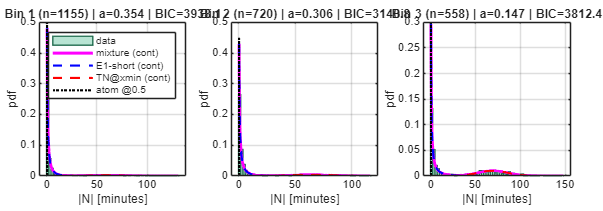


==== BIN 1 REMpre [0.50, 5.00) | n=1155 ====


a (atom at xmin) = 0.3541
w_cont = [0.8753 0.1247]
E1-short: r=0.132921
TN@xmin: mu=58.8130, sig=16.6844
LL=-1952.493061 | BIC=3938.06 | n=1155 | n_cont=746


Discrete GOF bin 1 (mapping=ceil): KS=0.0237 (p=0.215) | CvM=0.0001 (p=0.175) | Chi2=44.21 (p=0.555) | G=44.96 (p=0.56) | bins=42


  Early-point check (bin 1):


    P(X=0.5): obs=0.3541 | model=0.3541
    P(X=1.0): obs=0.1619 | model=0.1619
    P(X=1.5): obs=0.1074 | model=0.0885
    P(X=2.0): obs=0.0606 | model=0.0587
    P(X=2.5): obs=0.0433 | model=0.0426



==== BIN 2 REMpre [5.00, 12.00) | n=720 ====


a (atom at xmin) = 0.3056
w_cont = [0.7733 0.2267]
E1-short: r=0.112570
TN@xmin: mu=64.0311, sig=16.4390
LL=-1554.865308 | BIC=3140.80 | n=720 | n_cont=500


Discrete GOF bin 2 (mapping=ceil): KS=0.0194 (p=0.5) | CvM=0.0001 (p=0.25) | Chi2=51.26 (p=0.14) | G=50.59 (p=0.22) | bins=43


  Early-point check (bin 2):


    P(X=0.5): obs=0.3056 | model=0.3056
    P(X=1.0): obs=0.1264 | model=0.1457
    P(X=1.5): obs=0.0833 | model=0.0805
    P(X=2.0): obs=0.0722 | model=0.0539
    P(X=2.5): obs=0.0444 | model=0.0395



==== BIN 3 REMpre [12.00, 71.50) | n=558 ====


a (atom at xmin) = 0.1470
w_cont = [0.5231 0.4769]
E1-short: r=0.062951
TN@xmin: mu=69.4299, sig=16.2589
LL=-1890.783664 | BIC=3812.39 | n=558 | n_cont=476


Discrete GOF bin 3 (mapping=ceil): KS=0.0262 (p=0.115) | CvM=0.0002 (p=0.01) | Chi2=46.33 (p=0.855) | G=49.89 (p=0.81) | bins=62


  Early-point check (bin 3):


    P(X=0.5): obs=0.1470 | model=0.1470
    P(X=1.0): obs=0.0753 | model=0.1015
    P(X=1.5): obs=0.0609 | model=0.0575
    P(X=2.0): obs=0.0412 | model=0.0395
    P(X=2.5): obs=0.0358 | model=0.0297



%% ========================================================================
%  PER-REMpre BIN FITS + DISCRETE GOF using MAP_CHOSEN
%==========================================================================

edgesRP = [0.5 5 12 71.5];
nBins   = numel(edgesRP)-1;
binID   = discretize(RP_min, edgesRP);

figure('Color','w','Position',[100 100 1200 420]);
tiledlayout(1,3,'TileSpacing','compact','Padding','compact');

for b = 1:nBins
    xb_all = x_all(binID==b);
    xb_all = xb_all(isfinite(xb_all) & xb_all>=XMIN);

    nexttile;

    if numel(xb_all) < 80
        histogram(xb_all, max(10,round(numel(xb_all)/4)), 'Normalization','pdf', ...
            'FaceColor',face,'FaceAlpha',0.4,'EdgeColor','none');
        grid on; box on;
        xlabel('|N| [minutes]'); ylabel('pdf');
        title(sprintf('Bin %d (n=%d) | REMpre [%.2f, %.2f)', ...
            b, numel(xb_all), edgesRP(b), edgesRP(b+1)), 'Interpreter','none');
        continue;
    end

    fitB = fit_atom_e1tn(xb_all, opts, XMIN);

    fprintf('\n==== BIN %d REMpre [%.2f, %.2f) | n=%d ====\n', ...
        b, edgesRP(b), edgesRP(b+1), numel(xb_all));
    print_fit_console_atom(fitB);

    % Plot bin pdf overlay
    histogram(xb_all, nbinsHist, 'Normalization','pdf', ...
        'FaceColor',face,'FaceAlpha',0.35,'EdgeColor',edge,'LineWidth',1.0);
    hold on;

    xxB = linspace(min(xb_all), max(xb_all), 700);
    [yyB, compsB] = atom_e1tn_pdf_components(xxB, fitB, XMIN);

    plot(xxB, yyB, 'm-', 'LineWidth',2.2);
    plot(xxB, compsB(:,1), 'b--', 'LineWidth',1.6);
    plot(xxB, compsB(:,2), 'r--', 'LineWidth',1.6);

    yl = ylim;
    plot([XMIN XMIN], yl, 'k:', 'LineWidth',1.6);

    grid on; box on;
    xlabel('|N| [minutes]'); ylabel('pdf');
    title(sprintf('Bin %d (n=%d) | a=%.3f | BIC=%.1f', b, numel(xb_all), fitB.a, fitB.BIC), 'Interpreter','none');

    if b==1
        legend({'data','mixture (cont)','E1-short (cont)','TN@xmin (cont)','atom @0.5'}, 'Location','northeast');
    end

    % Discrete GOF per bin (chosen mapping)
    if DO_DISCRETE_GOF
        statsObsB = discrete_gof_stats(xb_all, fitB, XMIN, GRID_STEP, MIN_EXP, MAP_CHOSEN);

        if GOF_MODE == "plugin"
            [pvalsB, ~] = discrete_gof_bootstrap_plugin(xb_all, fitB, XMIN, GRID_STEP, MIN_EXP, B_BOOT, MAP_CHOSEN);
        else
            [pvalsB, ~] = discrete_gof_bootstrap_refit(xb_all, fitB, XMIN, GRID_STEP, MIN_EXP, B_BOOT, optsBoot, MAP_CHOSEN);
        end

        fprintf('Discrete GOF bin %d (mapping=%s): KS=%.4f (p=%.4g) | CvM=%.4f (p=%.4g) | Chi2=%.2f (p=%.4g) | G=%.2f (p=%.4g) | bins=%d\n', ...
            b, MAP_CHOSEN, statsObsB.KS, pvalsB.pKS, statsObsB.CvM, pvalsB.pCvM, statsObsB.Chi2, pvalsB.pChi2, statsObsB.G, pvalsB.pG, statsObsB.nBinsUsed);

        fprintf('  Early-point check (bin %d):\n', b);
        pmfB = atom_e1tn_pmf_grid(fitB, XMIN, GRID_STEP, max(xb_all), MAP_CHOSEN);
        for vv = PROB_POINTS
            obsP = mean(xb_all == vv);
            j = find(abs(pmfB.xg - vv) < 1e-12, 1);
            if isempty(j), modP = NaN; else, modP = pmfB.pg(j); end
            fprintf('    P(X=%.1f): obs=%.4f | model=%.4f\n', vv, obsP, modP);
        end
    end
end


%% ========================= LOCAL FUNCTIONS ==============================

function print_fit_console_atom(fit)
fprintf('a (atom at xmin) = %.4f\n', fit.a);
fprintf('w_cont = [%.4f %.4f]\n', fit.w(1), fit.w(2));
fprintf('E1-short: r=%.6f\n', fit.r1);
fprintf('TN@xmin: mu=%.4f, sig=%.4f\n', fit.mu2, fit.sig2);
fprintf('LL=%.6f | BIC=%.2f | n=%d | n_cont=%d\n', fit.loglik(end), fit.BIC, fit.n, fit.n_cont);
end

%% -------------------- FITTING --------------------

function fit = fit_atom_e1tn(x_all, opts, xmin)
x_all = x_all(:);
x_all = x_all(isfinite(x_all) & x_all>=xmin);

aHat = mean(x_all == xmin);

x = x_all(x_all > xmin);
n_cont = numel(x);

n = numel(x_all);

if n_cont < 30
    fit = struct('a',aHat,'w',[1 0],'r1',0.1,'mu2',mean(x_all),'sig2',std(x_all), ...
                 'loglik',-inf,'BIC',inf,'n',n,'n_cont',n_cont);
    return;
end

fitCont = fit2_e1_tnorm_mixture(x, opts, xmin);

fit = fitCont;
fit.a = aHat;
fit.n = n;
fit.n_cont = n_cont;

kpar = 5; % (a) + (w1) + r + mu + sig  => 5 free params
fit.BIC = -2*fit.loglik(end) + kpar*log(n_cont);
end

function fit = fit2_e1_tnorm_mixture(x, opts, xmin)
x = x(:);
x = x(isfinite(x) & x>xmin);
n = numel(x);

bestLL = -inf;
best = [];

r0 = clamp(0.05, opts.rMin, opts.rMax);

mu0  = quantile0(x, 0.75);
sig0 = clamp(0.5*(quantile0(x,0.75)-quantile0(x,0.25)), opts.sigMinTN, opts.sigMaxTN);
if ~isfinite(sig0) || sig0<=0
    sig0 = clamp(std(x), opts.sigMinTN, opts.sigMaxTN);
end

for s = 1:opts.nStarts
    w = rand(1,2); w = w/sum(w);
    w = clamp_weights2(w, opts);

    r1  = clamp(r0*(0.5 + 1.5*rand), opts.rMin, opts.rMax);

    mu2  = clamp(mu0*(0.8 + 0.8*rand), xmin, max(x));
    sig2 = clamp(sig0*(0.6 + 1.2*rand), opts.sigMinTN, opts.sigMaxTN);

    [w,r1,mu2,sig2,LL] = em2_e1_tnorm(x, w, r1, mu2, sig2, opts, xmin);

    if LL(end) > bestLL
        bestLL = LL(end);
        best = {w,r1,mu2,sig2,LL};
    end
end

[w,r1,mu2,sig2,LL] = best{:};

kpar = 4;
BIC  = -2*LL(end) + kpar*log(n);

fit = struct('w',w,'r1',r1,'mu2',mu2,'sig2',sig2, ...
             'loglik',LL,'BIC',BIC,'n',n);
end

function [w,r1,mu2,sig2,LL] = em2_e1_tnorm(x, w, r1, mu2, sig2, opts, xmin)
n = numel(x);
LL = zeros(opts.maxIter,1);
trimN = floor(opts.trimFrac*n);

for it = 1:opts.maxIter
    p1 = w(1) * e1short_pdf(x, r1, xmin);
    p2 = w(2) * tnorm_pdf_trunc(x, mu2, sig2, xmin);
    s  = p1 + p2;

    a1 = p1 ./ max(s, eps);
    a2 = p2 ./ max(s, eps);

    keep = true(n,1);
    if trimN > 0
        [~,idx] = sort(s,'ascend');
        keep(idx(1:trimN)) = false;
    end

    xk  = x(keep);
    a1k = a1(keep);
    a2k = a2(keep);

    w = [mean(a1k), mean(a2k)];
    w = clamp_weights2(w, opts);

    r1 = e1short_wmle_r(xk, a1k, r1, opts, xmin);

    [mu2, sig2] = tnorm_wmle_trunc_fminsearch(xk, a2k, mu2, sig2, opts, xmin);

    muFloor = max(max(xmin, opts.MU_FLOOR_MIN), quantile0(xk, opts.MU_FLOOR_Q));
    mu2 = max(mu2, muFloor);

    if opts.ENFORCE_TN_LONG_COND
        qcheck = quantile0(xk, opts.LONGTAIL_QCHECK);
        if qcheck >= opts.LONGTAIL_MIN_MINUTES
            muMinLong = quantile0(xk, opts.Q_TN_LONG);
            mu2 = max(mu2, muMinLong);
        end
    end

    sig2 = clamp(sig2, opts.sigMinTN, opts.sigMaxTN);

    p1k = w(1) * e1short_pdf(xk, r1, xmin);
    p2k = w(2) * tnorm_pdf_trunc(xk, mu2, sig2, xmin);
    LL(it) = sum(log(max(p1k+p2k, eps)));

    if it>1 && abs(LL(it)-LL(it-1)) < opts.tol*max(1,abs(LL(it-1)))
        LL = LL(1:it);
        break;
    end
end

LL = LL(1:it);
end

%% -------------------- MODEL PDF/CDF PARTS --------------------

function y = e1short_pdf(x, r, xmin)
x = x(:);
y = zeros(size(x));
ix = (x>=xmin) & isfinite(x);
Z = expint(max(r*xmin, realmin));
Z = max(Z, realmin);
y(ix) = exp(-r*x(ix)) ./ max(x(ix), realmin) ./ Z;
y(~isfinite(y)) = 0;
end

function F = e1short_cdf(x, r, xmin)
x = x(:);
F = zeros(size(x));
ix = (x>=xmin) & isfinite(x);
Z = expint(max(r*xmin, realmin));
Z = max(Z, realmin);
F(ix) = 1 - expint(max(r*x(ix), realmin)) ./ Z;
F = min(max(F,0),1);
end

function y = tnorm_pdf_trunc(x, mu, sig, a)
x = x(:);
sig = max(sig, realmin);
alpha = (a - mu)/sig;
Z = 1 - normcdf0(alpha);
Z = max(Z, realmin);

y = zeros(size(x));
ix = (x>=a) & isfinite(x);
z = (x(ix)-mu)/sig;
y(ix) = (normpdf0(z)./sig) ./ Z;
y(~isfinite(y)) = 0;
end

function F = tnorm_cdf_trunc(x, mu, sig, a)
x = x(:);
sig = max(sig, realmin);
alpha = (a - mu)/sig;
Fa = normcdf0(alpha);
Z  = 1 - Fa;
Z  = max(Z, realmin);

F = zeros(size(x));
ix = (x>=a) & isfinite(x);
z = (x(ix)-mu)/sig;
Fx = normcdf0(z);
F(ix) = (Fx - Fa) ./ Z;
F = min(max(F,0),1);
end

function [yy, comps] = atom_e1tn_pdf_components(xx, fit, xmin)
xx = xx(:);
comps = zeros(numel(xx),2);
contScale = (1 - fit.a);
comps(:,1) = contScale * fit.w(1) * e1short_pdf(xx, fit.r1, xmin);
comps(:,2) = contScale * fit.w(2) * tnorm_pdf_trunc(xx, fit.mu2, fit.sig2, xmin);
yy = sum(comps,2);
yy(xx < xmin) = 0;
comps(xx < xmin,:) = 0;
end

%% -------------------- DISCRETE MODEL PMF on GRID (mapping-aware) --------------------

function pmf = atom_e1tn_pmf_grid(fit, xmin, d, xMaxObs, mapMode)
% Build pmf over observed grid points xg = xmin, xmin+d, ..., xMaxObs.
% MapMode determines which latent interval contributes to each observed grid point.
xMaxObs = max(xMaxObs, xmin);
xg = (xmin:d:xMaxObs)';   % observed support points

% Continuous CDF function handle
Fcont = @(t) min(max( fit.w(1)*e1short_cdf(t, fit.r1, xmin) + fit.w(2)*tnorm_cdf_trunc(t, fit.mu2, fit.sig2, xmin), 0), 1);

pg = zeros(size(xg));

switch string(mapMode)
    case "floor"
        % X = xmin + d*floor((X*-xmin)/d): latent in [xk, xk+d) maps to xk
        edges = [xg; xg(end)+d];
        Fc = Fcont(edges);
        pBins = max(Fc(2:end) - Fc(1:end-1), 0);
        pg = (1-fit.a) * pBins;
        pg(1) = pg(1) + fit.a;

    case "ceil"
        % X = xmin + d*ceil((X*-xmin)/d): latent in (xk-d, xk] maps to xk (k>=2).
        % The smallest observed value xmin comes only from the atom at xmin.
        pg(1) = fit.a;
        if numel(xg) >= 2
            for k = 2:numel(xg)
                lo = xg(k-1);
                hi = xg(k);
                pg(k) = (1-fit.a) * max(Fcont(hi) - Fcont(lo), 0);
            end
        end

    case "nearest"
        % X = xmin + d*round((X*-xmin)/d):
        % Bin around each grid point: [xk-d/2, xk+d/2), truncated at xmin.
        for k = 1:numel(xg)
            lo = xg(k) - d/2;
            hi = xg(k) + d/2;
            lo = max(lo, xmin);
            if k == 1
                % include atom at xmin in first point
                pg(k) = fit.a + (1-fit.a) * max(Fcont(hi) - Fcont(lo), 0);
            else
                pg(k) = (1-fit.a) * max(Fcont(hi) - Fcont(lo), 0);
            end
        end

    otherwise
        error('Unknown mapMode: %s', mapMode);
end

pg = max(pg, 0);
pg = pg / max(sum(pg), eps);

pmf.xg = xg;
pmf.pg = pg;
pmf.mapMode = mapMode;
end

%% -------------------- DISCRETE GOF STATS --------------------

function stats = discrete_gof_stats(x_obs, fit, xmin, d, minExp, mapMode)
x_obs = x_obs(:);
x_obs = x_obs(isfinite(x_obs) & x_obs>=xmin);
n = numel(x_obs);

pmf = atom_e1tn_pmf_grid(fit, xmin, d, max(x_obs), mapMode);
xg = pmf.xg; pg = pmf.pg;

% Observed counts aligned to xg
[ux,~,ic] = unique(x_obs);
cnt = accumarray(ic,1);
obsCounts = zeros(size(xg));
[tf,loc] = ismember(ux, xg);
obsCounts(loc(tf)) = cnt(tf);

Fn = cumsum(obsCounts)/n;
Fmod = cumsum(pg);

KS = max(abs(Fn - Fmod));
CvM = sum((Fn - Fmod).^2 .* pg); % weighted CvM on grid

expCounts = n * pg;
[obsM, expM] = merge_tail_bins(obsCounts, expCounts, minExp);

Chi2 = sum((obsM - expM).^2 ./ max(expM, eps));
G = 2*sum(obsM .* log(max(obsM,eps)./max(expM,eps)));

stats.KS = KS;
stats.CvM = CvM;
stats.Chi2 = Chi2;
stats.G = G;
stats.n = n;
stats.nBinsUsed = numel(obsM);
end

function [obsM, expM] = merge_tail_bins(obsCounts, expCounts, minExp)
obsM = obsCounts(:);
expM = expCounts(:);

while numel(expM) > 1 && any(expM < minExp)
    idx = find(expM < minExp, 1, 'last');
    if idx == 1
        obsM(2) = obsM(2) + obsM(1);
        expM(2) = expM(2) + expM(1);
        obsM(1) = [];
        expM(1) = [];
    else
        obsM(idx-1) = obsM(idx-1) + obsM(idx);
        expM(idx-1) = expM(idx-1) + expM(idx);
        obsM(idx) = [];
        expM(idx) = [];
    end
end
end

%% -------------------- DISCRETE BOOTSTRAP (PLUGIN) --------------------

function [pvals, nullStats] = discrete_gof_bootstrap_plugin(x_obs, fitHat, xmin, d, minExp, B, mapMode)
x_obs = x_obs(:);
x_obs = x_obs(isfinite(x_obs) & x_obs>=xmin);
n = numel(x_obs);

obs = discrete_gof_stats(x_obs, fitHat, xmin, d, minExp, mapMode);

nullStats.KS   = zeros(B,1);
nullStats.CvM  = zeros(B,1);
nullStats.Chi2 = zeros(B,1);
nullStats.G    = zeros(B,1);

for b = 1:B
    xb = sample_from_model_to_grid(fitHat, n, xmin, d, mapMode);
    sb = discrete_gof_stats(xb, fitHat, xmin, d, minExp, mapMode);
    nullStats.KS(b)   = sb.KS;
    nullStats.CvM(b)  = sb.CvM;
    nullStats.Chi2(b) = sb.Chi2;
    nullStats.G(b)    = sb.G;
end

pvals.pKS   = mean(nullStats.KS   >= obs.KS);
pvals.pCvM  = mean(nullStats.CvM  >= obs.CvM);
pvals.pChi2 = mean(nullStats.Chi2 >= obs.Chi2);
pvals.pG    = mean(nullStats.G    >= obs.G);
end

%% -------------------- DISCRETE BOOTSTRAP (REFIT) --------------------

function [pvals, nullStats] = discrete_gof_bootstrap_refit(x_obs, fitHat, xmin, d, minExp, B, optsBoot, mapMode)
x_obs = x_obs(:);
x_obs = x_obs(isfinite(x_obs) & x_obs>=xmin);
n = numel(x_obs);

obs = discrete_gof_stats(x_obs, fitHat, xmin, d, minExp, mapMode);

nullStats.KS   = zeros(B,1);
nullStats.CvM  = zeros(B,1);
nullStats.Chi2 = zeros(B,1);
nullStats.G    = zeros(B,1);

for b = 1:B
    xb = sample_from_model_to_grid(fitHat, n, xmin, d, mapMode);
    fitB = fit_atom_e1tn(xb, optsBoot, xmin);
    sb = discrete_gof_stats(xb, fitB, xmin, d, minExp, mapMode);

    nullStats.KS(b)   = sb.KS;
    nullStats.CvM(b)  = sb.CvM;
    nullStats.Chi2(b) = sb.Chi2;
    nullStats.G(b)    = sb.G;
end

pvals.pKS   = mean(nullStats.KS   >= obs.KS);
pvals.pCvM  = mean(nullStats.CvM  >= obs.CvM);
pvals.pChi2 = mean(nullStats.Chi2 >= obs.Chi2);
pvals.pG    = mean(nullStats.G    >= obs.G);
end

%% -------------------- SAMPLING: MODEL -> GRID (mapping-aware) --------------------

function xg = sample_from_model_to_grid(fit, n, xmin, d, mapMode)
x = sample_atom_e1tn_latent(fit, n, xmin);

switch string(mapMode)
    case "floor"
        k = floor((x - xmin)/d);
    case "ceil"
        k = ceil((x - xmin)/d);
    case "nearest"
        k = round((x - xmin)/d);
    otherwise
        error('Unknown mapMode: %s', mapMode);
end

k(k<0) = 0;
xg = xmin + d*k;
end

function xs = sample_atom_e1tn_latent(fit, n, xmin)
u = rand(n,1);
isAtom = (u <= fit.a);

xs = zeros(n,1);
xs(isAtom) = xmin;

nC = sum(~isAtom);
if nC > 0
    xs(~isAtom) = sample_e1tn_cont_latent(fit, nC, xmin);
end
end

function xs = sample_e1tn_cont_latent(fit, n, xmin)
u = rand(n,1);
isShort = (u <= fit.w(1));
n1 = sum(isShort);
n2 = n - n1;

xs = zeros(n,1);
if n1 > 0
    xs(isShort) = e1short_rnd_reject(n1, fit.r1, xmin);
end
if n2 > 0
    xs(~isShort) = tnorm_rnd_trunc_ge_a(fit.mu2, fit.sig2, n2, xmin);
end
end

function x = e1short_rnd_reject(n, r, xmin)
x = zeros(n,1);
filled = 0;
while filled < n
    m = max(2000, 2*(n-filled));
    t = xmin + (-log(rand(m,1)))./max(r, realmin);
    acc = rand(m,1) < (xmin ./ max(t, realmin));
    t = t(acc);
    take = min(numel(t), n-filled);
    if take > 0
        x(filled+1:filled+take) = t(1:take);
        filled = filled + take;
    end
end
end

function x = tnorm_rnd_trunc_ge_a(mu, sig, n, a)
sig = max(sig, realmin);
x = zeros(n,1);
filled = 0;
while filled < n
    m = max(2000, 2*(n-filled));
    z = mu + sig*randn(m,1);
    z = z(z>=a);
    take = min(numel(z), n-filled);
    if take > 0
        x(filled+1:filled+take) = z(1:take);
        filled = filled + take;
    end
end
end

%% -------------------- Normal helpers (toolbox-free) -------------------------

function y = normpdf0(z)
y = exp(-0.5*z.^2) / sqrt(2*pi);
end

function F = normcdf0(z)
F = 0.5*(1 + erf(z./sqrt(2)));
end

%% -------------------- Utilities --------------------------------------------

function w = clamp_weights2(w, opts)
w = max(w, opts.wMin);
w = w / sum(w);
w = min(max(w, opts.wMin), opts.wMax);
w = w / sum(w);
end

function y = clamp(x, lo, hi)
y = min(max(x, lo), hi);
end

function q = quantile0(x, p)
x = sort(x(:));
n = numel(x);
if n==0, q = NaN; return; end
p = min(max(p,0),1);
h = (n-1)*p + 1;
hf = floor(h);
hc = ceil(h);
if hf==hc
    q = x(hf);
else
    q = x(hf) + (h-hf)*(x(hc)-x(hf));
end
end

function [muHat, sigHat] = tnorm_wmle_trunc_fminsearch(x, r, mu0, sig0, opts, a)
x = x(:); r = max(r(:),0);
den = max(sum(r), eps);
if den <= 0
    muHat = mu0; sigHat = sig0; return;
end

m = sum(r.*x)/den;
v = sum(r.*(x-m).^2)/den;

mu0 = max(mu0, a);
sig0 = clamp(max(sig0, sqrt(max(v,1e-6))), opts.sigMinTN, opts.sigMaxTN);

p0 = [mu0, log(sig0)];
obj = @(p) tnorm_trunc_negwll(p, x, r, opts, a);

p = fminsearch(obj, p0, optimset('Display','off', 'MaxIter',300, 'TolX',1e-6, 'TolFun',1e-6));

muHat  = max(p(1), a);
sigHat = exp(p(2));
sigHat = clamp(sigHat, opts.sigMinTN, opts.sigMaxTN);
end

function val = tnorm_trunc_negwll(p, x, r, opts, a)
mu  = p(1);
sig = exp(p(2));
sig = clamp(sig, opts.sigMinTN, opts.sigMaxTN);

alpha = (a - mu)/sig;
Fa = normcdf0(alpha);
Z  = 1 - Fa;
Z  = max(Z, realmin);

z = (x - mu)/sig;
logpdf = log(normpdf0(z)./sig) - log(Z);

bad = (x<a) | ~isfinite(logpdf);
logpdf(bad) = -1e6;

val = -sum(r .* logpdf);
if ~isfinite(val), val = realmax; end
end

function rHat = e1short_wmle_r(x, wts, r0, opts, xmin)
x = x(:);
wts = max(wts(:),0);
if sum(wts) <= 0
    rHat = r0; return;
end
p0 = log(max(r0, opts.rMin));
obj = @(p) e1short_negwll_r(p, x, wts, opts, xmin);
p = fminsearch(obj, p0, optimset('Display','off','MaxIter',250,'TolX',1e-6,'TolFun',1e-6));
rHat = clamp(exp(p), opts.rMin, opts.rMax);
end

function val = e1short_negwll_r(p, x, wts, opts, xmin)
r = clamp(exp(p), opts.rMin, opts.rMax);
Z = expint(max(r*xmin, realmin));
Z = max(Z, realmin);
logpdf = -r*x - log(max(x,realmin)) - log(Z);
bad = (~isfinite(logpdf)) | (x < xmin);
logpdf(bad) = -1e6;
val = -sum(wts .* logpdf);
if ~isfinite(val), val = realmax; end
end